clear all; clc;
warning('off','all')

# Exercise 3.8

Derive the equations of motion using the Lagrange's method for the 2-link manipulators shown in the figure below, which are constrained to have $p_{e1} = p_{e2}$ .

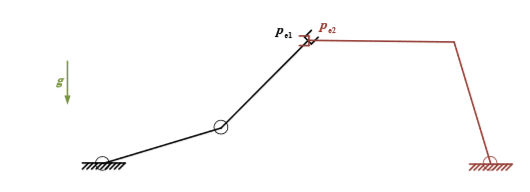

*NOTE: In this exercise we use the results for the 2-link manipulator in exercise 3.7, to get:*

- *Pend,*

- *inertiaMatrix*

- *KineticEnergy*

- *PotentialEnergy*

## Numerical values:

L1 = 1;
L2 = 1;

b_f = 10;

% since there are two manipulators defined in the base frame,
% an offset along x is added to the manipulator on the right.
offset = L1+L2;

% initial condition that satisfies the constraint
q10 = [50;-10]*pi/180;
q20 = sym('q20',[2,1]);
eq = Pend(q10) - (Pend(q20) + [offset;0;0]) == [0;0;0]; 
solution = solve(eq.',q20);
temp1 = vpa(solution.q201);
temp2 = vpa(solution.q202);
q20 = double([temp1(1);temp2(1)]);
q0dot = [0; 0];

Ts = 1e-2;

## Symbolic variables:

lambda = sym('lambda',[3,1]);  % Lagrange multipliers

q1 = sym('q1', [2,1]);
dq1 = sym('dq1', [2,1]);
ddq1 = sym('ddq1', [2,1]);
tau1 = sym('tau1', [2,1]);

q2 = sym('q2', [2,1]);
dq2 = sym('dq2', [2,1]);
ddq2 = sym('ddq2', [2,1]);
tau2 = sym('tau2', [2,1]);

Q = [q1; q2];
dQ = [dq1; dq2];
ddQ = [ddq1; ddq2];
Tau = [tau1; tau2];

## Constraints:

The manipulators are constrained to move so that their end-effector share the same position:


$$        \phi(q_1,q_2)
        =
        p_{e1}(q_1) - p_{e2}(q_2) 
        =0, \ \ \text{with} \ \ p_{e1},p_{e2} \in \mathbb{R}^3 \  \ \text{and} \  \ q_1,q_2 \in \mathbb{R}^2$$


From this, we compute the constraint Jacobian:


$$J_\phi(Q)
=
\left[ \matrix{
\frac{\partial{\phi}}{\partial{q_1}} & \frac{\partial{\phi}}{\partial{q_2}} 
 }\right]
=
\left[ \matrix{
\frac{\partial{\phi_1}}{\partial{q_1}}  & \frac{\partial{\phi_1}}{\partial{q_2 }} \cr
\frac{\partial{\phi}_2}{\partial{q_1}} & \frac{\partial{\phi_2}}{\partial{q_2 }} \cr
\frac{\partial{\phi}_3}{\partial{q_1}} & \frac{\partial{\phi_3}}{\partial{q_2 }} 
 }\right]
=
\left[ \matrix{
J_{\phi_1}(q) \cr J_{\phi_2}(q) \cr J_{\phi_3}(q)
 }\right], \ \  \text{where} \ \ Q=\left[\matrix{q_1 \cr q_2}\right]$$


constraint = Pend(q1) - (Pend(q2) + [offset;0;0])

$$constraint = \left(\begin{array}{c} \cos\left(q_{11}\right)-\cos\left(q_{21}\right)+\cos\left(q_{11}\right)\,\cos\left(q_{12}\right)-\cos\left(q_{21}\right)\,\cos\left(q_{22}\right)-\sin\left(q_{11}\right)\,\sin\left(q_{12}\right)+\sin\left(q_{21}\right)\,\sin\left(q_{22}\right)-2\\ \sin\left(q_{11}\right)-\sin\left(q_{21}\right)+\cos\left(q_{11}\right)\,\sin\left(q_{12}\right)+\cos\left(q_{12}\right)\,\sin\left(q_{11}\right)-\cos\left(q_{21}\right)\,\sin\left(q_{22}\right)-\cos\left(q_{22}\right)\,\sin\left(q_{21}\right)\\ 0 \end{array}\right)$$

simplify(constraint)

$$ans = \left(\begin{array}{c} \cos\left(q_{11}+q_{12}\right)-\cos\left(q_{21}+q_{22}\right)+\cos\left(q_{11}\right)-\cos\left(q_{21}\right)-2\\ \sin\left(q_{11}+q_{12}\right)-\sin\left(q_{21}+q_{22}\right)+\sin\left(q_{11}\right)-\sin\left(q_{21}\right)\\ 0 \end{array}\right)$$


dConstraint_Q = jacobian(constraint,Q);
simplify(dConstraint_Q)

$$ans = \left(\begin{array}{cccc} -\sin\left(q_{11}+q_{12}\right)-\sin\left(q_{11}\right) & -\sin\left(q_{11}+q_{12}\right) & \sin\left(q_{21}+q_{22}\right)+\sin\left(q_{21}\right) & \sin\left(q_{21}+q_{22}\right)\\ \cos\left(q_{11}+q_{12}\right)+\cos\left(q_{11}\right) & \cos\left(q_{11}+q_{12}\right) & -\cos\left(q_{21}+q_{22}\right)-\cos\left(q_{21}\right) & -\cos\left(q_{21}+q_{22}\right)\\ 0 & 0 & 0 & 0 \end{array}\right)$$

ddConstraint_Q = jacobian(dConstraint_Q*dQ,Q);

## Dynamic model with constraint:


$$B(q)\ddot{q} + C(q, \dot{q} )\dot{q} + g(q) + J_\phi^T (q)\lambda= \tau $$


KineticEnergyTotal = KineticEnergy(q1,dq1) + KineticEnergy(q2,dq2);
PotentialEnergyTotal = PotentialEnergy(q1) + PotentialEnergy(q2);
Lagrangian = KineticEnergyTotal - PotentialEnergyTotal - lambda.'*constraint;
%simplify(Lagrangian)

dLag_dQ  = jacobian(Lagrangian, dQ).';
dLag_Q   = jacobian(Lagrangian, Q).';
ddLag_dQ = jacobian(dLag_dQ, dQ);
ddLag_Q  = jacobian(dLag_dQ, Q);

inertiaMatrix = ddLag_dQ; % B
gVector = jacobian(PotentialEnergyTotal,Q).'; % g
coriolisMatrix = ddLag_Q*dQ - jacobian(KineticEnergyTotal,Q).'; % C
frictionOnJoints = -b_f*dQ; % F

% Check if correct (should be zero):
simplify(dLag_Q + dConstraint_Q.'*lambda + gVector - jacobian(KineticEnergyTotal,Q).')               

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

## Closed-form solution to Lagrange multipliers:


$$\left[ \matrix{ B(q)  & J_\phi^T(q) \cr
             J_\phi(q) & 0} \right]
\left[ \matrix{ \ddot{q} \cr 
\lambda } \right]
=
\left[ \matrix{\tau - n(q,\dot{q}) \cr
 -\dot{J}_\phi(q) \dot{q} }\right]$$


where $n (q,\dot{q}) = C(q,\dot{q})\dot{q}+g(q)$

modifiedInertiaMatrix = [ddLag_dQ         dConstraint_Q.';
                         dConstraint_Q        zeros(3,3)];

RHS = [Tau + frictionOnJoints - (coriolisMatrix + gVector);
       -ddConstraint_Q*dQ]; 
%simplify(RHS)

matlabFunction(modifiedInertiaMatrix,'File','modifiedInertiaMatrix','Vars',{q1,q2});
matlabFunction(RHS,'File','RHS','Vars',{q1,dq1,tau1,q2,dq2,tau2});

## Simulation:

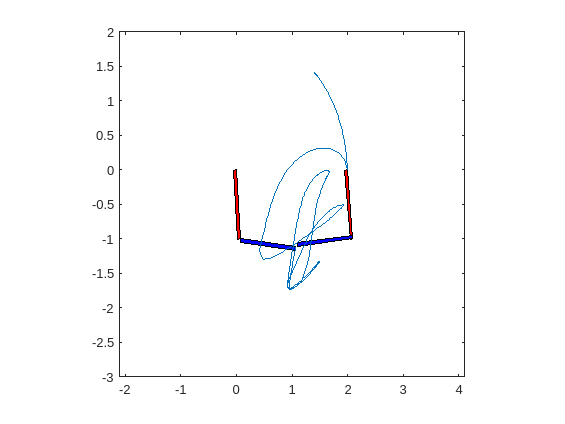

sim('simulation');
pause(1);
visualization;